# 2. 信号・画像データの基本操作

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## 信号の読み込みと表示

信号は1次元のベクトルとして格納される（nはサンプル数）．

n = 512;

信号の読み込み．

u = load_signal('Piece-Regular', n); % 要素数nの1次元信号

n行1列の列ベクトルにする．

u = u(:);

信号の各要素を[0,1]にスケーリング．

u = rescale(u,0,1);

信号の表示．

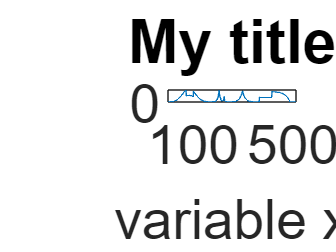

clf;
plot(1:n, u);
axis('tight');
title('My title'); % 図のタイトル
set_label('variable x', 'variable y'); % 各軸

サブプロットを使って複数の図を表示できる．

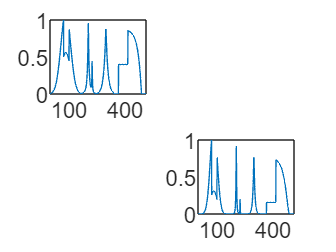

subplot(2, 2, 1); % 2x2の表示枠の左上にプロット
plot(u); axis('tight');
subplot(2, 2, 4); % 右下の枠にプロット
plot(u.^2); axis('tight');

複数の信号を同じ図に表示することも可能．

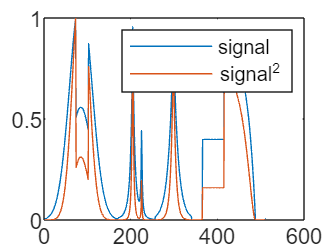

clf;
plot(1:n, [u u.^2]');
legend('signal', 'signal^2');

## 画像の読み込みと表示

画像を読み込む．

name = 'sunflower_gray';
u = load_image(name, []); % 画像の読み込み（[]部分でサイズを指定できる）

中心部を256x256でくり抜いた画像を生成．

ucrop = crop(u,256);
help crop

  crop - crop an image to reduce its size
 
    M = crop(M,n,c);
 
    n is the new size of the image
    c is the center of the crop
 
    Copyright (c) 2007 Gabriel Peyre



表示．

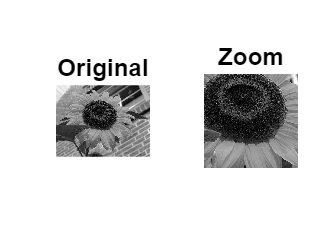

clf;
imageplot(u, 'Original', 1,2,1);
imageplot(ucrop, 'Zoom', 1,2,2);

カラー画像を読み込む．

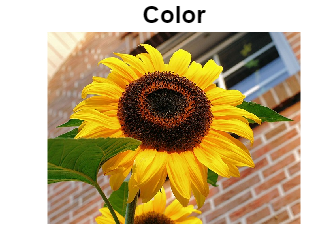

clf;
name = 'sunflower';
uc = load_image(name, []); % 画像の読み込み（[]部分でサイズを指定できる）
imageplot(uc, 'Color');

モノクロ画像は2次元配列，カラー画像は3次元配列（3次元方向にRGBの色情報を格納）になっている※．

※ カラー画像の場合，R，G，Bの順に格納されている．

size(u) % モノクロ画像データのサイズ（行，列）

ans =    486   640


size(uc) % カラー画像データのサイズ（行，列，奥行き）

ans =    486   640     3


カラー画像はRGB成分を平均することでモノクロ画像に変換できる（平均法）．

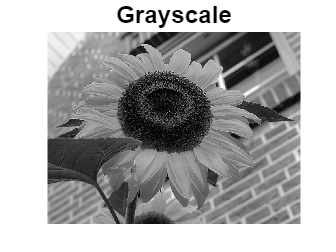

clf;
u2 = sum(uc,3); % 三次元方向に和をとる
u2 = rescale(u2,0,1); % 正規化
imageplot(u2, 'Grayscale');

## **演習問題**

**演習2-1**: 上記のカラー画像変換では平均法によってモノクロ画像に変換したが，実際には画像に対し様々なグレースケール化が存在する．平均法以外のグレースケール化法を調べ，画像を変換せよ（どのグレースケール化法を使用したのかコメントに記載すること）．また，平均法と自分で実装したグレースケール化法で得られた画像を並べて比較せよ

Rec.ITU-R BT.601-7 と呼ばれる、加重平均によってグレースケール化する。

`0.2989 * R + 0.5870 * G + 0.1140 * B `

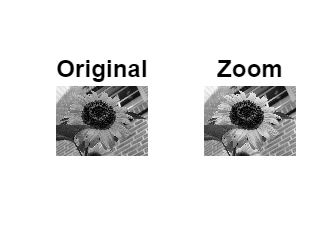

clf;
u3 = u2;
for i = 1:size(u3,1)
    for j = 1:size(u3,2)
        u3(i,j) = 0.2989 * uc(i,j,1) + 0.5870 * uc(i,j,2) + 0.1140 * uc(i,j,3) ;
    end
end
imageplot(u2, 'Original', 1,2,1);
imageplot(u3, 'Zoom', 1,2,2);

花弁や葉の部分が少し明るく見える。

**演習2-2**: グレースケール画像'sunflower_gray'を読み込み，4分割の右上部分をくり抜いて表示せよ．また，左右を反転させた画像を表示せよ．

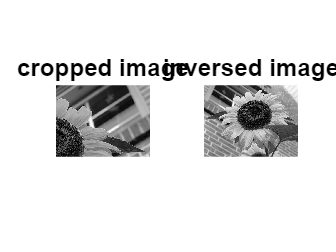

clf;
ucrop = crop(u,[243,320],[122,480]);
imageplot(ucrop, 'cropped image',1,2,1);
u4 = u2;
for i = 1:size(u3,1)
    for j = 1:size(u3,2)
        u4(i,j) = u3(i,641-j);
    end
end
imageplot(u4, 'inversed image',1,2,2);

**演習2-3**: グレースケール画像'sunflower_gray'を読み込み，縦と横に画素を8個飛ばしでサンプリングした画像とそのサイズを表示せよ．

clf;
height = fix(size(u2, 1)/8);
width = fix(size(u2, 2)/8);
u5 = zeros(height, width);

for i = 1:height
    for j = 1:width
        u5(i,j) = u2(8*(i-1)+1,8*(j-1)+1);
    end
end
size(u5)

ans =     60    80


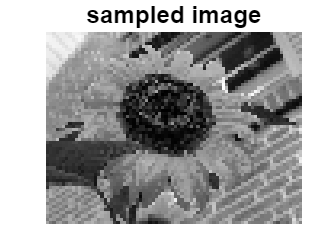

imageplot(u5, 'sampled image');

**演習2-4**: グレースケール画像'sunflower_gray'を読み込み，画素をランダムに半数欠落させた画像を表示せよ．欠落部分は画素値0を代入すること．

ヒント：randpermを使うと楽

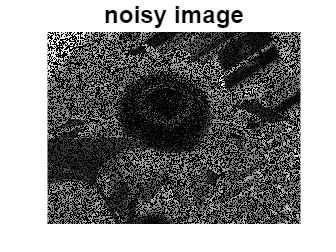

clf;
u6 = u2;
for i = 1:size(u2, 1)
    selected = randperm(size(u2, 2),fix(size(u2, 2)/2));
    for j = 1:fix(size(u2, 2)/2)
        u6(i,selected(j)) = 0;
    end
end

imageplot(u6, 'noisy image');

**演習2-5**: グレースケール画像'sunflower_gray'を読み込み，全画素値の平均値をしきい値として白黒に2値化（255 or 0）した画像を表示せよ．

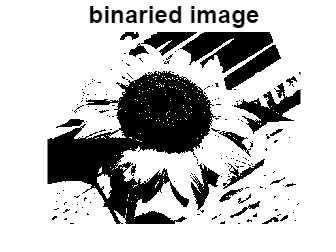

clf;
mid = 0;
for i = 1:size(u2,1)
    for j = 1:size(u2,2)
        mid = mid + u2(i,j);
    end
end
mid = mid / (size(u2, 1) * size(u2, 2));

u7 = u2;
for i = 1:size(u2,1)
    for j = 1:size(u2,2)
        if u7(i,j) < mid
            u7(i,j) = 0;
        else 
            u7(i,j) = 1;
        end
    end
end

imageplot(u7, 'binaried image');